## Read Task File

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mohammad\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "AMICA" v1.5.2 (see >> help eegplugin_amica)
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "FASTER1.2.3b" v1.2.3b (see >> help eegplugin_FASTER)
EEGLAB: adding "FastICA" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata) - new version 2.4 available
EEGLAB: add

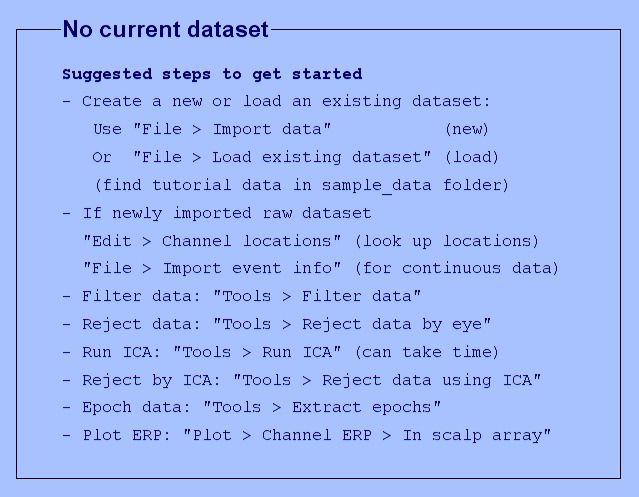

You are using the latest version of EEGLAB.


clear all
eeglab

T = readtable('task_track_file.csv','Format','%d%s%s%s%s%s%s%s')

T = 75×8 table
    Var1        local_file_path                 raw_data_file_name                         preprocessed_one                              ERP_mat_file                                    PAC_dist                                   PAC_dist_mean_channel                                   Rank_Stage                   
    ____    _______________________    ____________________________________    ________________________________________    ________________________________________    _____________________________________________    _____________________________________________    ________________________________________________

      0     {'sub-001\ses-01\eeg\'}    {'sub-001_ses-01_task-Rest_eeg.set'}    {'pre

Path = {'D:\Mastersharif\MasterProject\data\parkinsons-oddball'};
files_preprocessed = fullfile(Path,T{:,2},T{:,8});
% flags = zeros(size(files_preprocessed));
% for i = 1:size(files_preprocessed, 2)
%     flags(i) = exist(files_preprocessed{i}, "file");
% end
flag=isfile(files_preprocessed);
task_not_completed = find(flag==0)';
temp = size(task_not_completed);

a = T{:,4}
a{5}

## Preprocess

Highpass_low = 1; % in Hz
Highpass_High = 150; % in Hz
Notch_low = 59.9; % in Hz
Notch_High = 60.1;% in Hz
Notch_order = 16500;
num_stages = 10;
Rank = struct('Rank_stage_1',0,'Rank_stage_2',0);
Path = 'D:\\Mastersharif\\MasterProject\\data\\parkinsons-oddball';
% Path = '/home/kiani/DS/ds003490-download';
channellocationfile = fullfile({Path},T{1,2}{1},'sub-001_ses-01_task-Rest_electrodes.tsv');
channellocationfile = channellocationfile{1}

channellocationfile = 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-001\ses-01\eeg\sub-001_ses-01_task-Rest_electrodes.tsv'

a=T{:,2};
b=T{:,3};
c=T{:,8};
delete(gcp('nocreate'))
% parpool(2)

parfor k=1:size(task_not_completed,2)
    i = task_not_completed(k);
    load_path = fullfile(Path, a{i}); %sprintf('%s/%s',Path,a{i});
    EEG = pop_loadset(b{i},load_path);
    temp = zeros(1,num_stages) 
    EEG = pop_chanedit(EEG,'load',{channellocationfile ,'filetype','autodetect'});
    temp(1,1) = rank(EEG.data);
    EEG = pop_select( EEG, 'nochannel',{'X','Y','Z','VEOG'});
    temp(1,2) = rank(EEG.data);
    EEG = pop_eegfiltnew(EEG, 'locutoff',Highpass_low,'hicutoff',Highpass_High);
    EEG = pop_eegfiltnew(EEG, 'locutoff',Notch_low,'hicutoff',Notch_High,'filtorder',Notch_order,'revfilt',1);
    temp(1,3) = rank(EEG.data);
    EEG1 = pop_clean_rawdata(EEG, 'FlatlineCriterion',5,'ChannelCriterion',0.8,'LineNoiseCriterion',12,'Highpass','off','BurstCriterion','off','WindowCriterion','off','BurstRejection','off','Distance','Euclidian');
    temp(1,4) = rank(EEG1.data);
    EEG = pop_interp(EEG1, EEG.chanlocs, 'spherical');
    temp(1,5) = rank(EEG.data);
    EEG = pop_reref( EEG, []);
    temp(1,6) = rank(EEG.data);
    EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion','off','LineNoiseCriterion','off','Highpass','off','BurstCriterion',15,'WindowCriterion','off','BurstRejection','off','Distance','Euclidian');
    temp(1,7) = rank(EEG.data);
    EEG = pop_reref( EEG, []);
    temp(1,8) = rank(EEG.data);
    temp(1,9) = rank(EEG.data);
    fullfile(load_path,c{i})
    temp_func(fullfile(load_path,c{i}),temp);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
pop_loadset(): loading file D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-001\ses-01\eeg\sub-001_ses-01_task-Rest_eeg.set ...
pop_loadset(): loading file D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-001\ses-02\eeg\sub-001_ses-02_task-Rest_eeg.set ...
pop_loadset(): loading file D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-002\ses-01\eeg\sub-002_ses-01_task-Rest_eeg.set ...
pop_loadset(): loading file D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-002\ses-02\eeg\sub-002_ses-02_task-Rest_eeg.set ...
Reading float file 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-001\ses-01\eeg\sub-001_ses-01_task-Rest_eeg.fdt'...
readlocs(): 'tsv' format assumed from file extension
Channel structure size not consistent with the data so changes will be ignored
Use the function pop_select(EE

    main_stimuli_name = {'S200','S201','S202'};
    ERP = container.Map()
    for i=1:3
        index = find(strcmp({EEG(1).event(122:end).type},main_stimuli_name{i})==1) + 121;
        time_index = [EEG(1).event(index).latency];
        temp = repmat( time_index,601,1);
        matrix_time_index = temp + period_samples';
        Stimuli = EEG(1).data(1:63,matrix_time_index);
        Stimuli = reshape(Stimuli',601,30,63);
        ERP_temp = mean(Stimuli,2);
        ERP(main_stimuli_name{i}) = reshape(ERP_temp,601,63);
    end
    save_path_file = fullfile(c{i},load_path)
    temp_func(save_path_file,ERP);

Test  loading EEG location channel

clear all
Path_to_set_file = 'C:\Users\mohammad\Documents\Check_FASTER\sub-002\ses-01\eeg';
% channellocationfile = fullfile('D:\Mastersharif\semister2\neurosience\HW3\eeglab2021.0\sample_locs','Standard-10-20-Cap81.locs');
channellocationfile = fullfile('D:\Mastersharif\MasterProject\data\parkinsons-oddball','sub-001_ses-01_task-Rest_electrodes (2).tsv');

EEG = pop_loadset('sub-002_ses-01_task-Rest_eeg.set',Path_to_set_file);

pop_loadset(): loading file C:\Users\mohammad\Documents\Check_FASTER\sub-002\ses-01\eeg\sub-002_ses-01_task-Rest_eeg.set ...
Reading float file 'C:\Users\mohammad\Documents\Check_FASTER\sub-002\ses-01\eeg\sub-002_ses-01_task-Rest_eeg.fdt'...


EEG = pop_chanedit(EEG,'lookup',channellocationfile);  

readlocs(): 'tsv' format assumed from file extension
Channel lookup: no location for VEOG,X,Y,Z
Send us standard location for your channels at eeglab@sccn.ucsd.edu


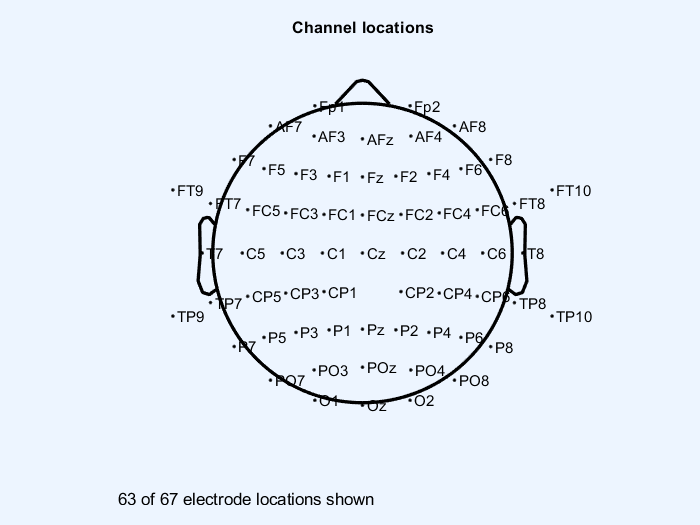

% chanlocs = readlocs(channellocationfile);
figure; topoplot([],EEG.chanlocs, 'style', 'blank',  'electrodes', 'labelpoint', 'chaninfo', EEG.chaninfo);

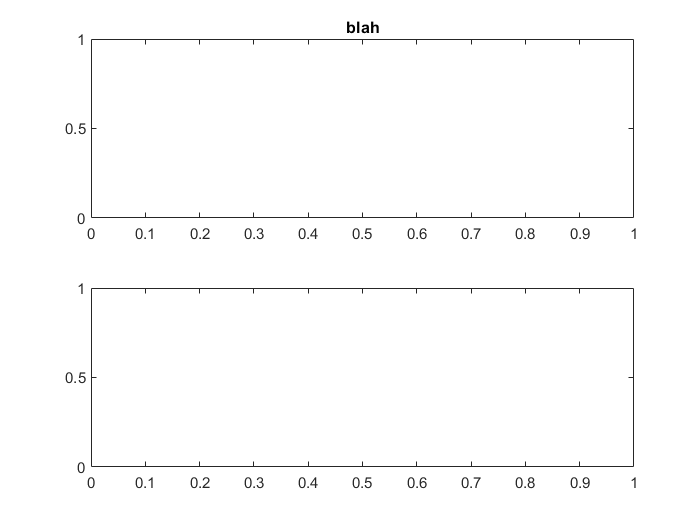

figure;  
subplot(2, 1, 1);
plot(nan, nan);
subplot(2, 1, 2);
plot(nan, nan);
currentFigure = gcf;
title(currentFigure.Children(end), 'blah');

clear all
close all
duration_of_erp_epoch = 100; % in ms
number_sample = 100/2; 
high_frequency = 100;
low_frequency = 20;
load('channel_name.mat')
Path_save_PAC_Vec = 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\results\PAC_vector';
stimulus_type = {'Target','Standard','Novelty'};
group_type = {'PD ON','PD Off', 'CTL'};
duration_str = num2str(duration_of_erp_epoch);
frequency_low_str = num2str(low_frequency);
frequency_high_str = num2str(high_frequency);
folder_name = [duration_str '_' frequency_low_str '-' frequency_high_str];
fixed_dir_path = [Path_save_PAC_Vec '\'  folder_name];
height = 1900;
width = 1200;
x=0;y=0;
title_name = ['dur-' duration_str '-' 'fre-range' '-' frequency_low_str '-' frequency_high_str];
f=figure('Position', [x y width height]);
i=1

i = 1

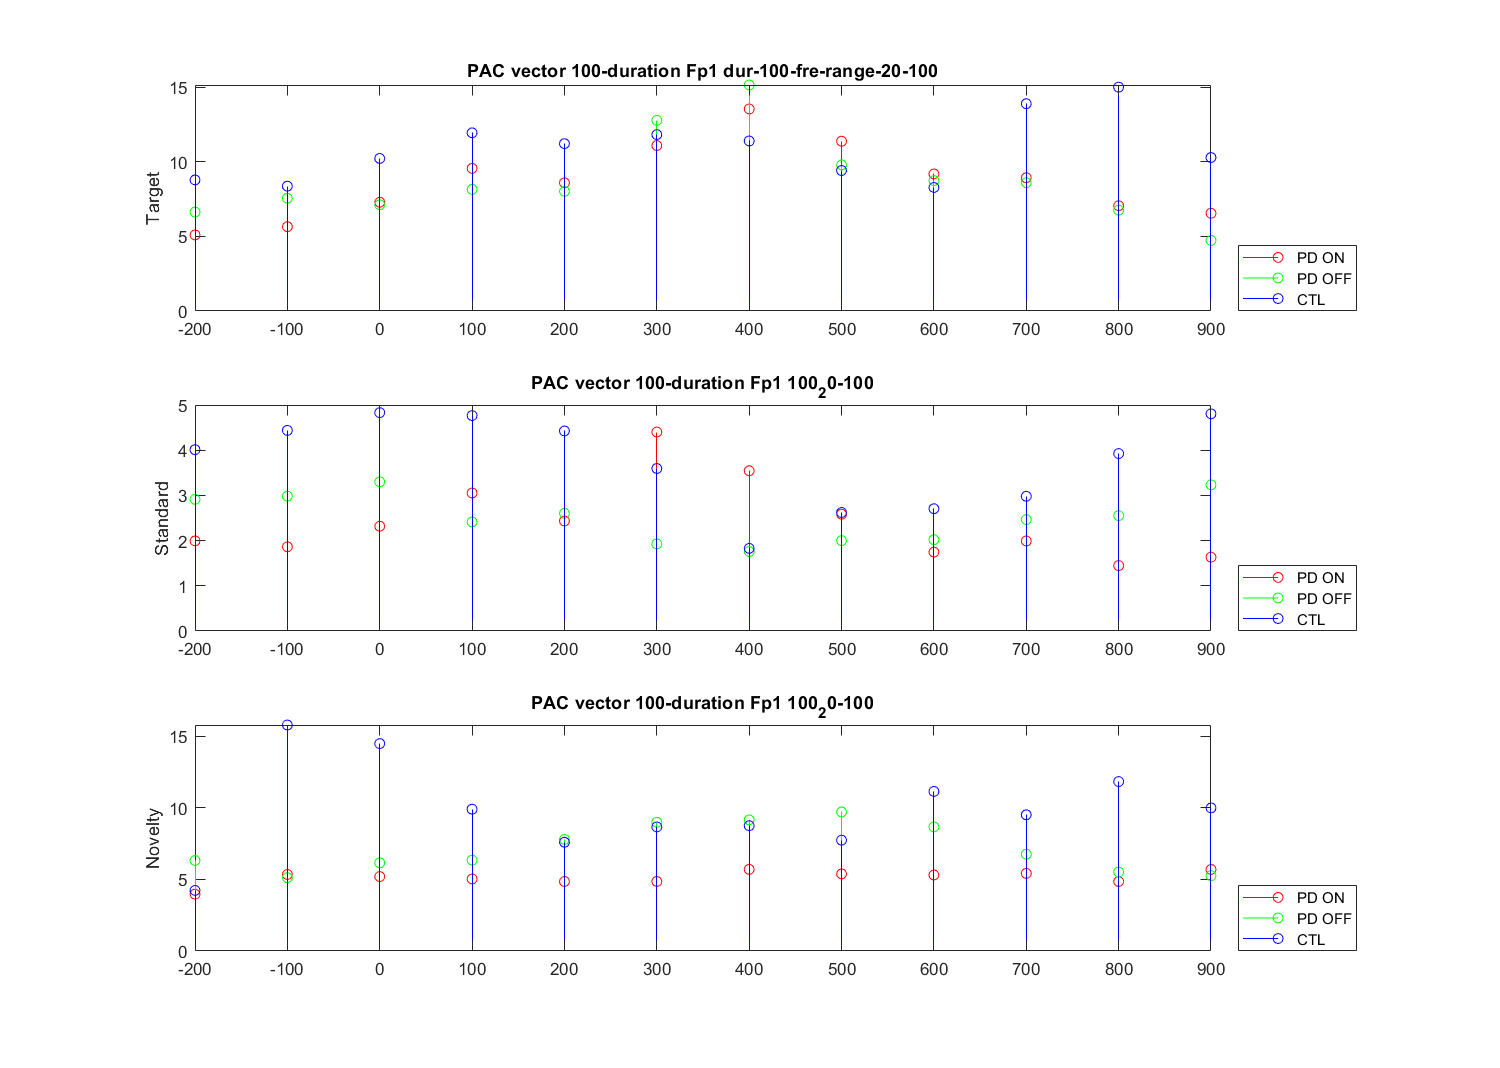

for h=1:3
    num_plot = h;
    subplot(3,1,num_plot)

    file_name = ['Channel' channel_name{i} '.mat'];
    a = load(fullfile(fixed_dir_path,group_type{1},stimulus_type{h},file_name));
    a = struct2cell(a);
    PAC_vector_mean_1 = mean(a{1},1);
    a = load(fullfile(fixed_dir_path,group_type{2},stimulus_type{h},file_name));
    a = struct2cell(a);
    PAC_vector_mean_2 = mean(a{1},1);
    a = load(fullfile(fixed_dir_path,group_type{3},stimulus_type{h},file_name));
    a = struct2cell(a);
    PAC_vector_mean_3 = mean(a{1},1);
    time = -200:100:900;  
    
    num_com = length(PAC_vector_mean_1);
    stem(time,PAC_vector_mean_1,'Color','r')
    xlim([-200,900])
    hold on
    stem(time,PAC_vector_mean_2,'Color','g')
    xlim([-200,900])
    hold on
    stem(time,PAC_vector_mean_3,'Color','b')
    xlim([-200,900])
    ylabel(stimulus_type{h})
    title(['PAC vector 100-duration ' channel_name{i} ' ' folder_name])
    legend('PD ON','PD OFF','CTL','Location','southeastoutside')
end
currentFigure = gcf;
title(currentFigure.Children(end), ['PAC vector 100-duration ' channel_name{i} ' ' title_name]);
figure_path_save = fullfile(Path_save_PAC_Vec,'picture','Same_stimulus_type',folder_name,[channel_name{i},'.png']);
saveas(f,figure_path_save)

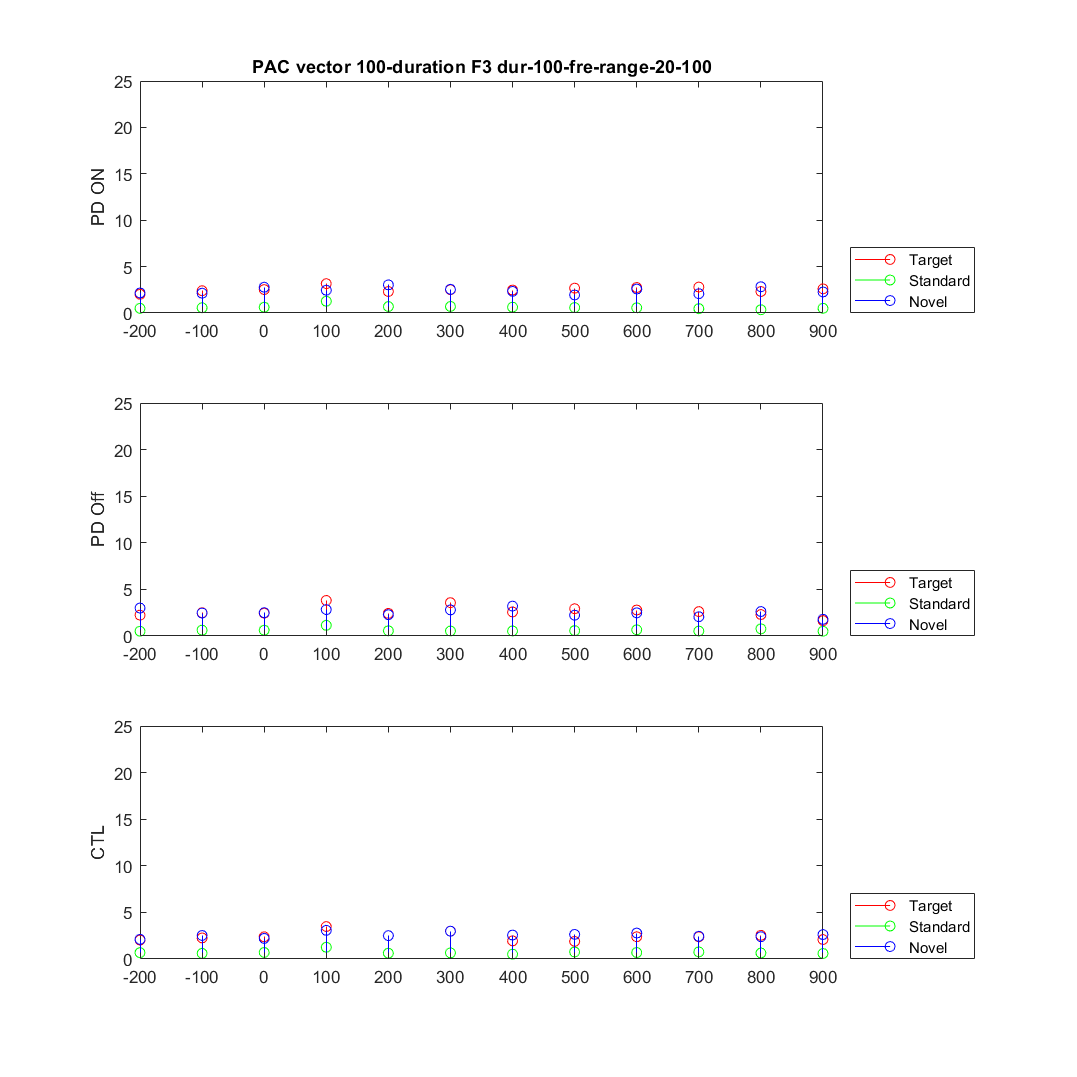

height = 1000;
width = 1000;
title_name = ['dur-' duration_str '-' 'fre-range' '-' frequency_low_str '-' frequency_high_str];
x=0;y=0;
f=figure('Position', [x y width height]);
channel_name = 'F3';
for h=1:3
    num_plot = h;
    subplot(3,1,num_plot)
%         ERP_target = reshape(ERP_collection(h,:,1,i,:),25,601);
%         ERP_standard = reshape(ERP_collection(h,:,2,i,:),25,601);
%         ERP_novelty = reshape(ERP_collection(h,:,3,i,:),25,601);
%         PAC_vector_target =  zeros(25,floor(601/duration_of_erp_epoch));
%         PAC_vector_standard = zeros(25,floor(601/duration_of_erp_epoch));
%         PAC_vector_novelty = zeros(25,floor(601/duration_of_erp_epoch));
%         for k=1:25
%             for j=1:(floor(601/duration_of_erp_epoch))
%                 PAC_vector_target(k,j) = tfMVL(ERP_target(k,(j-1)*number_sample+1:j*number_sample),high_frequency,low_frequency,500);
%                 PAC_vector_standard(k,j) = tfMVL(ERP_standard(k,(j-1)*number_sample+1:j*number_sample),high_frequency,low_frequency,500);
%                 PAC_vector_novelty(k,j) = tfMVL(ERP_novelty(k,(j-1)*number_sample+1:j*number_sample),high_frequency,low_frequency,500);
%             end
%         end
%         temp = fullfile(Path_save_PAC_Vec,['Channnel' channel_name{i} ' ' group_type{h} ' ' num2str(duration_of_epoch) ' ']);
%         temp1 = ['Channnel' channel_name{i} ' ' group_type{h} ' ' num2str(duration_of_epoch) ' '];
%         temp = directories{h}
%         save([temp, '\' stimulus_type{1} '.mat'],'PAC_vector_target')
%         save([temp, '\' stimulus_type{2} '.mat'],'PAC_vector_standard')
%         save([temp, '\' stimulus_type{3} '.mat'],'PAC_vector_novelty')
    file_name = ['Channel' channel_name '.mat'];
    load(fullfile(fixed_dir_path,group_type{h},stimulus_type{1},file_name))
    load(fullfile(fixed_dir_path,group_type{h},stimulus_type{2},file_name))
    load(fullfile(fixed_dir_path,group_type{h},stimulus_type{3},file_name))
    
    PAC_vector_target_mean = mean(PAC_vector_target,1);
    PAC_vector_novelty_mean = mean(PAC_vector_novelty,1);
    PAC_vector_standard_mean = mean(PAC_vector_standard,1);
    time = -200:100:900;

    max_y_range = 25;
    stem(time,PAC_vector_target_mean,'Color','r')
    xlim([-200,900])
    ylim([0,max_y_range])
    hold on
    stem(time,PAC_vector_standard_mean,'Color','g')
    xlim([-200,900])
    ylim([0,max_y_range])
    hold on
    stem(time,PAC_vector_novelty_mean,'Color','b')
    xlim([-200,900])
    ylim([0,max_y_range])
    ylabel(group_type{h})
%         title(['PAC vector 100-duration ' channel_name{i} ' ' folder_name])
    legend('Target','Standard','Novel','Location','southeastoutside')
end
currentFigure = gcf;
title(currentFigure.Children(end), ['PAC vector 100-duration ' channel_name ' ' title_name]);
% figure_path_save = fullfile(Path_save_PAC_Vec,'picture','Same_group',folder_name,[channel_name{i},'.png']);
exportgraphics(currentFigure,'test1.png','Resolution',300)